# Tests for debugging purposes

## The equations

## 
$$g(X,Q) = \sum_j \|X-Y_jQ_j\|^2 
\\
\nabla g(X,Q) = 2\bigg(\sum_j(X-Y_jQ_j), Y^\top(YQ-X)\bigg)
\\
\nabla^2 g(X,Q)[U,V] = \nabla g(U,V)$$


## Nonconvex problem

### Data and problem

clear
n=5; % data dimension
k=5; % number of matrices
r=round(n/2); % size of factorization Y of data A
p=r+1; % size of factorization X of barycenter B (r<=p)
A = data(n,k,r);
prob = nonconvex_problem(A,r,p);

### Gradient

The slope should be 2. It appears to be: 2.00001.
If it is far from 2, then directional derivatives might be erroneous.


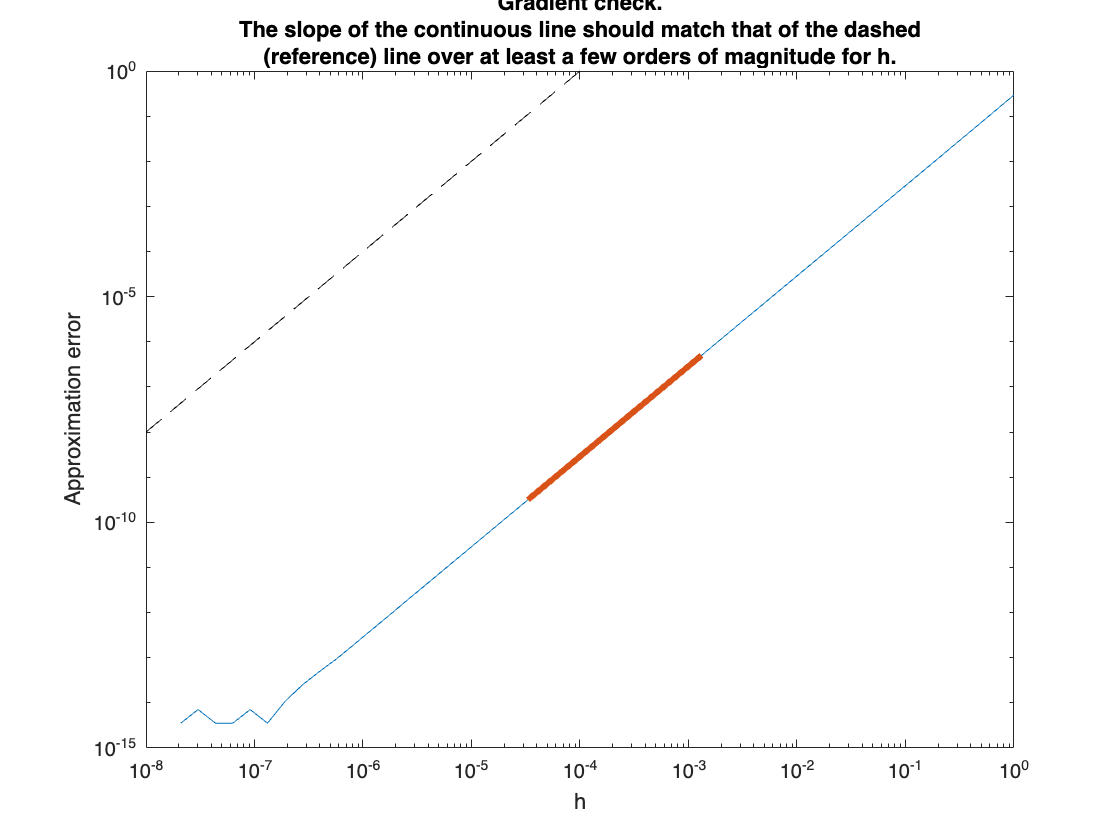

The residual should be 0, or very close. Residual: 1.51208e-15.
If it is far from 0, then the gradient is not in the tangent space.
In certain cases (e.g., hyperbolicfactory), the tangency test is inconclusive.


checkgradient(prob);

### Hessian

checkhessian(prob);

The slope should be 3. It appears to be: 3.00036.
If it is far from 3, then directional derivatives,
the gradient or the Hessian might be erroneous.
Tangency residual should be zero, or very close; residual: 3.04147e-16.
If it is far from 0, then the Hessian is not in the tangent space.
||a*H[d1] + b*H[d2] - H[a*d1+b*d2]|| should be zero, or very close.
	Value: 4.53142e-16 (norm of H[a*d1+b*d2]: 1.66209)
If it is far from 0, then the Hessian is not linear.
<d1, H[d2]> - <H[d1], d2> should be zero, or very close.
	Value: 0.0930706 - 0.0930706 = 6.93889e-17.
If it is far from 0, then the Hessian is not symmetric.


### Optimization

clear
n=32; % data dimension
k=10; % number of matrices
r=round(n/2); % size of factorization Y of data A
p=r+5; % size of factorization X of barycenter B (r<=p)
A = data(n,k,r);
prob = nonconvex_problem(A,r,p);

options.debug=0;
%options.statsfun = @variance_statsfun;
[x, xcost, info, options] = trustregions(prob,[],options);

           iter                  cost val     grad. norm    numinner     hessvec   numstored   stopreason
              0   +1.1741059303963859e+03   7.321077e+01
acc TR+       1   +9.3360429329473743e+02   6.173398e+01           1           1           1   exceeded trust region
acc TR+       2   +5.9370382605998736e+02   3.804584e+01           1           1           1   exceeded trust region
acc TR+       3   +3.5476498809330803e+02   1.343351e+01           2           2           2   negative curvature
REJ TR-       4   +3.5476498809330803e+02   1.343351e+01           2           2           2   exceeded trust region
acc TR+       5   +3.1429096340154911e+02   1.471360e+01           1           0           2   exceeded trust region
REJ TR-       6   +3.1429096340154911e+02   1.471360e+01           3           3           2   exceeded trust region
acc TR+       7   +2.8896724432634579e+02   9.330497e+00           1           0           2   exceeded trust region
acc           8   +2.

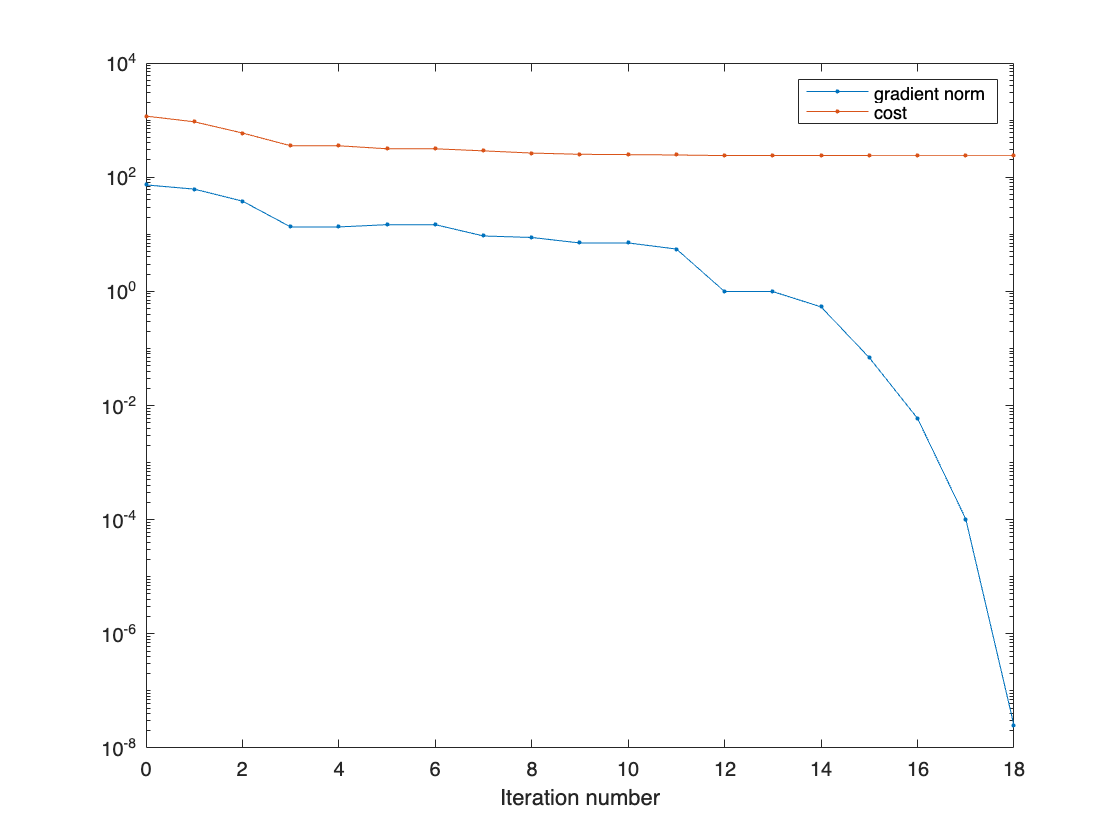

figure;
semilogy([info.iter], [info.gradnorm], '.-',[info.iter],[info.cost],'.-');
xlabel('Iteration number');
legend("gradient norm","cost")

## Convex problem

### Data and problem

clear
n=2; % data dimension
k=4; % number of matrices
A = data(n,k,n-1);
prob2 = convex_problem(A);

### Gradient

The slope should be 2. It appears to be: 2.00411.
If it is far from 2, then directional derivatives might be erroneous.


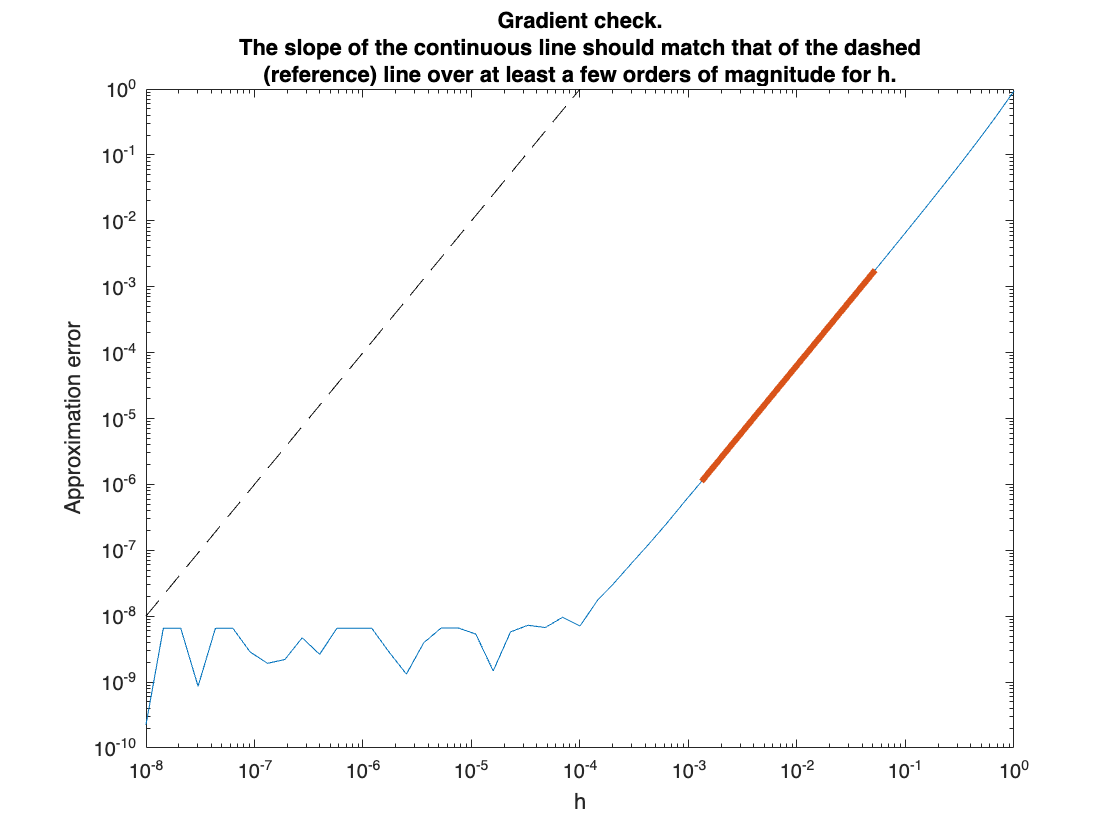

The residual should be 0, or very close. Residual: 1.18678e-18.
If it is far from 0, then the gradient is not in the tangent space.
In certain cases (e.g., hyperbolicfactory), the tangency test is inconclusive.


checkgradient(prob2);

### Manopt optimization

clear
n=4; % data dimension
k=10; % number of matrices
A = data(n,k,2);
prob2 = convex_problem(A);

% options.debug=1;
% options.statsfun = @variance_statsfun;
[x, xcost, info, options] = trustregions(prob2);

           iter                  cost val     grad. norm    numinner     hessvec   numstored   stopreason
              0   +4.9372478146704299e+00   1.015264e+00
acc TR+       1   +4.6176061017336139e+00   6.558877e-01           1           1           1   exceeded trust region
acc           2   +4.3501099316169292e+00   3.749140e-01           3           3           2   reached target residual-kappa (linear)
acc           3   +4.2230284651935373e+00   1.834978e-01           2           2           2   reached target residual-kappa (linear)
acc           4   +4.1647252399832002e+00   9.731692e-02           2           2           2   reached target residual-kappa (linear)
acc           5   +4.1332045156297657e+00   5.696577e-02           3           3           2   reached target residual-theta (superlinear)
acc           6   +4.1148476282251440e+00   3.377705e-02           4           4           2   reached target residual-theta (superlinear)
acc           7   +4.1032745584095265e+0

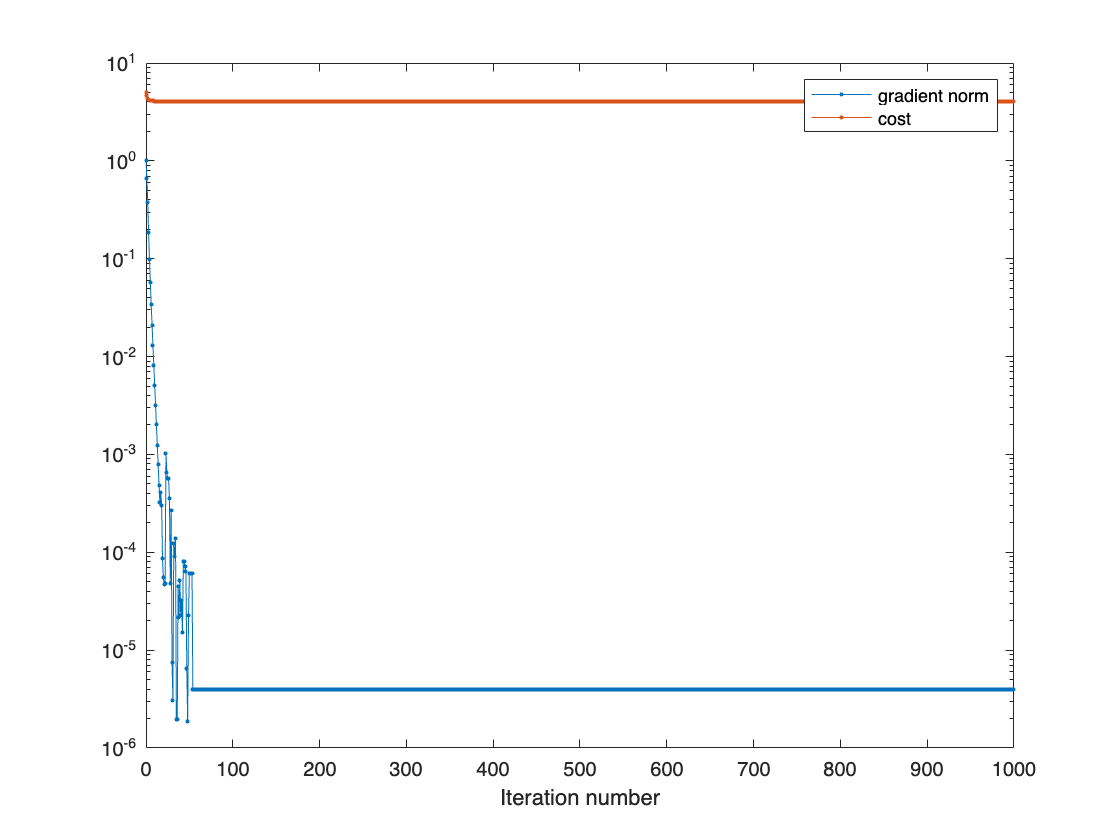

figure;
semilogy([info.iter], [info.gradnorm], '.-',[info.iter],[info.cost],'.-');
xlabel('Iteration number');
legend("gradient norm","cost")

### CVX optimization

clear
n=4; % data dimension
k=10; % number of matrices
r=1;
A = data(n,k,r);
[B,Bcost,info] = cvx_solve(A)

B =     0.9932    0.3986   -0.0715    0.1490
    0.3986    0.7247    0.2538    0.1397
   -0.0715    0.2538    0.2326    0.4067
    0.1490    0.1397    0.4067    1.6869


Bcost = 4.0837

info = struct with fields:
     cvx_status: 'Inaccurate/Solved'
     cvx_slvitr: 26
     cvx_slvtol: 1.7292e-07
     cvx_optbnd: 4.0837
    cvx_cputime: 2.1200


disp(eig(B))

    0.0000
    0.5580
    1.2009
    1.8786



### Manopt VS CVX

clear
n=4; % data dimension
k=10; % number of matrices
r=1;
A = data(n,k,r);
prob = convex_problem(A);
options.verbosity = 0;
s
[B, Bcost, info, options] = trustregions(prob,[],options);

[B_cvx,Bcost_cvx,info_cvx] = cvx_solve(prob.A);
B_relative_error =norm(B-B_cvx,"fro")/norm(B_cvx,"fro")

relative_error = 3.2853e-05